[popAudio,FS] = audioread("200805_002.WAV");

figure;plot(popAudio(:,1))

starttime = 3*60+45;

endtime = 3*60+50;
% starttime = 30;
% endtime = 70;

popAudioL = popAudio(starttime*FS + 1:endtime*FS + 1,1);
popAudioR = popAudio(starttime*FS + 1:endtime*FS + 1,2);

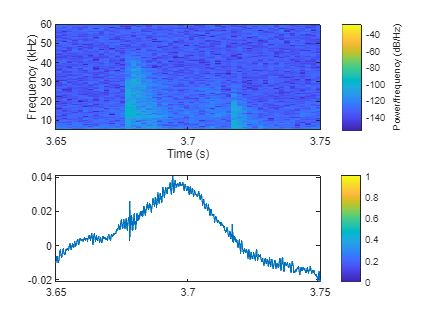

figure(1); subplot(211); spectrogram(popAudioL,hann(512),128,512,FS,'yaxis');
hold on;
hold off;
 xlim([3.65 4.15]);
 ylim([5 60]);


t = 0:1/FS:(length(popAudioL)-1)/FS;
figure(1); subplot(212); plot(t,popAudioL); colorbar;
 xlim([3.65 4.15]);